clear all
d=load('2015_irrigation_percentage_resampled.mat');
data=d.LC;
d1=load("E:\MTP2\lulc\LC_2015_masked.mat");
d1=d1.LC;
d_LC=(d1(2:130,2:136,1));

lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));

for i=1:129
    for j=1:135
        if isnan(d_LC(i,j))
            
            crop1(i,j)=nan;
        end
    end
end

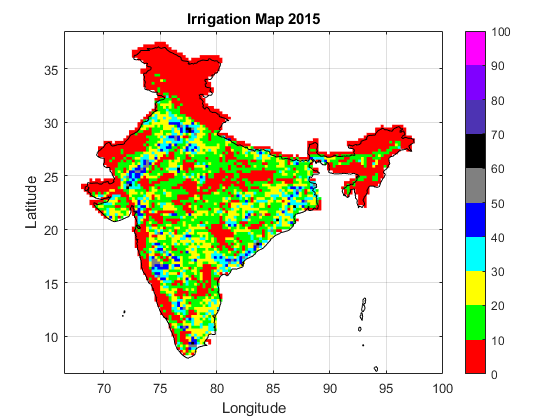

map = [1 0 0
    0 1 0
    1 1 0
    0 1 1
    0 0 1
    0.5 0.5 0.5
    0 0 0
    0.3 0.2 0.7
    0.5 0 1
    1 0 1];
f=figure(1);
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
set(gca,'YDir','normal')
cb1 = colorbar('Ticks',[0,10,20,30,40,50,60,70,80,90,100],...
         'TickLabels',{'0','10','20','30','40','50','60','70','80','90','100'});
cb1=colormap((map));
caxis([0 100])
ax1=gca;
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
title("Irrigation Map 2015"); % Putting title to the figure
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
saveas(f,"E:\MTP2\MTP2 final results\Irrigation_percentage_map2015.jpg");